# Filtro AR (ecuacion de Yule-Walker)

**La ecuación de Yule-Walker** es un conjunto de ecuaciones que se utilizan en el análisis de procesos estocásticos, particularmente en el modelado de **procesos autorregresivos** (AR). Estas ecuaciones se derivan de la relación entre los **coeficientes autoregresivos** de un modelo AR y las **funciones de autocovarianza** de la serie temporal.

% Generar una señal con ruido blanco
N = 500; % Número de muestras
n = 0:N-1;  % Eje temporal

%xn = 20 + 0.05 * n; % Tendencia lineal
xn = 3*cos(2*pi*0.01*n) - 2*sin(2*pi*0.05*n);
ruido = randn(1, N); % Ruido aleatorio
xn_r = xn + ruido;

Estimar las autocovarianzas de la señal

max_lag = 5; % Numero de atrasos
autocovarianzas = zeros(1, max_lag + 1);

for h = 0:max_lag
    autocovarianzas(h+1) = mean( xn_r(1:end-h) .* xn_r(h+1:end) );
    %autocovarianzas(h+1) = mean((xn_r(1:end-h) - mean(xn_r(1:end-h)) ) .* (xn_r(h+1:end) - mean(xn_r(h+1:end)) ));
end

Construir la matriz de autocovarianzas R

R = zeros(max_lag + 1);
for i = 1:max_lag+1
    for j = 1:max_lag+1
        R(i,j) = autocovarianzas(abs(i-j)+1);
    end
end

Resolver la ecuación de Yule-Walker para obtener los coeficientes AR

gamma = autocovarianzas(2:end); % Vector de autocovarianzas
phi_estimada = R(2:end, 2:end) \ gamma.'; % Resolver R * phi = gamma

Filtrando la señal con los coeficientes estimados

yn = filter([0, phi_estimada'], 1,xn_r);

Generando las graficas

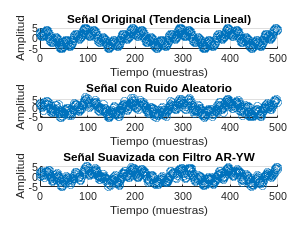

figure()

% Graficar la señal original (tendencia)
subplot(3,1,1);
scatter(n, xn);
title('Señal Original (Tendencia Lineal)');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal ruidosa
subplot(3,1,2);
scatter(n, xn_r);
title('Señal con Ruido Aleatorio');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal suavizada (filtro AR)
subplot(3,1,3);
scatter(n, yn);
title('Señal Suavizada con Filtro AR-YW');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

## Mediciones sobre las señales

Se aplicaran mediciones para verificar el efecto del filtro AR

Primero entre la señal original y la señal ruidosa

% Error cuadratico medio (MSE)
Err1 = (1/(N-max_lag)) *(sum( (xn(max_lag:end) - xn_r(max_lag:end)) .^ 2))

Err1 = 1.0876

Ahora entre la señal original y la señal suavizada

Err2 = (1/(N-max_lag)) *(sum( (xn(max_lag:end) - yn(max_lag:end)) .^ 2))

Err2 = 0.8588